# Practical Assignment 1: Accoustic localisation

Names:

NetIDs:

clear; clf; clc; close all;
addpath data
addpath functions

## 1. Calibration

load('calibration.mat')

### a) Measurement errors of each microphone at each sound pulse

The error at time step k for microphone j is given by:


$${\epsilon_{k,j} =\;y}_{k,j} -\frac{1}{8}\sum_{j=1}^8 y_{k,j}$$


% First get the means of all the TOA measurements
means = mean(y_toa')';
% Subtract the means (true value) to get the error of each sensor at each
% timestep
meas_errors = y_toa - means 

meas_errors = 1.0e-04 *

    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
         0         0         0         0         0    0.2268         0   -0.2268
    0.0850    0.0850    0.0850    0.0850    0.0850    0.0850   -0.1417   -0.3685
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834
         0         0         0         0         0    0.2268         0   -0.2268
    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834
    0.0283    0.0283    0.0283    0.0283    0.0283    0.0283    0.0283   -0.1984
    0.1134    0.1134    0.1134   -0.1134    0.1134    0.1134   -0.1134   -0.3401
   -0.0567    0.1701   -0.0567   -0.0567    0.1701    0.1701   -0.0567   -0.2834


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(meas_errors,"1a"))

correct


### b) Measurement bias $b_i$ of each microphone

The bias for each microphone is the average of the errors for that microphine across all time steps. So if we have N time steps:


$$b_j =\frac{1}{N}\sum_{k=1}^N \epsilon_{k,j}$$


% Take the average error across all time steps to get the bias for each
% sensor
biases = mean(meas_errors)

biases = 1.0e-04 *

    0.0293    0.0870    0.0293   -0.0437    0.1023    0.1292   -0.0591   -0.2743


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(biases,"1b"))

correct


### c) Variance $\sigma_i^2$of the measurement noise $e_i$ of each microphone

The variance of the measurement error for each microphone is given by:


$$\textrm{Cov}\left\lbrace \epsilon_{k,j} \right\rbrace =\textrm{Cov}\left\lbrace b_j +e_{k,j} \right\rbrace =\textrm{Cov}\left\lbrace b_j \right\rbrace +\textrm{Cov}\left\lbrace e_{k,j} \right\rbrace$$


However, the bias is deterministic, so it has 0 variance. Therefore, we are left with:


$$\textrm{Cov}\left\lbrace \epsilon_{k,j} \right\rbrace =\textrm{Cov}\left\lbrace e_{k,j} \right\rbrace =\sigma_j^2 =E\left\lbrace {\left(\epsilon_{k,j} -b_j \right)}^2 \right\rbrace$$


**FILL THIS IN**

% Use MATLAB's var function
vars = var(meas_errors)

vars = 1.0e-10 *

    0.4653    0.4484    0.4653    0.3583    0.4184    0.4052    0.3526    0.3448


Uncomment the following two lines to check if your answer is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(vars,"1c"))

correct


### d) Visualisation and interpretation of the measurement errors 

From the histograms of the measurement errors for the eight different microphones, we can see that each microphone has a different error distribution. As a result, each microphone's error has a different mean and variance, meaning that individual calibration for each microphone will be more effective for characterizing the noise. 

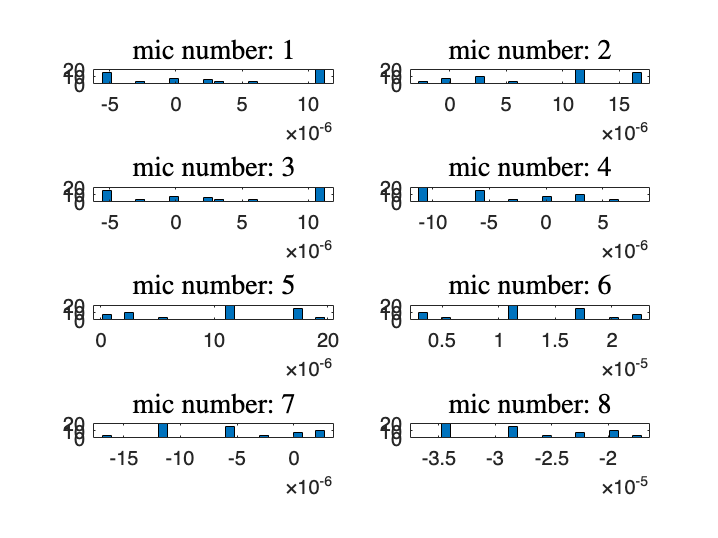

figure(1); clf;
for i = 1:size(y_toa,2)
    subplot(4,2,i);
    [N, l] = hist(meas_errors(:,i),20);
    Wb     = l(2)-l(1); % Bin widths
    Ny     = length(meas_errors(:,i)); % Nr of samples
    bar(l, N);
    title(['mic number: ',num2str(i)],'Interpreter','Latex','Fontsize',14)
end

## 2. Nonlinear least squares

load('experiment1.mat')
load('ground_truth1.mat')

### a) Nonlinear function $f$, and the noise covariance $\Sigma$

**Your text here** (*Please you the equation editor for equations)* **:**

The nonlinear function f is:


$${f\left(\theta_k \right)}_j =\tau_k +\frac{1}{c}\sqrt{{\left(y_k -m_{y,j} \right)}^2 +{\left(x_k -m_{x,j} \right)}^2 }+b_j$$


where $m_{y,j}$and $m_{x,j}$ are the microphone x and y positions and $b_j$ is the microphone bias. We can then stack these equations for each microphone into a vector of functions:


$$f\left(\theta_k \right)=\left\lbrack \begin{array}{c}
\tau_k +\frac{1}{c}\sqrt{{\left(y_k -m_{y,1} \right)}^2 +{\left(x_k -m_{x,1} \right)}^2 }+b_1 \\
\tau_k +\frac{1}{c}\sqrt{{\left(y_k -m_{y,2} \right)}^2 +{\left(x_k -m_{x,2} \right)}^2 }+b_2 \\
\ldotp \ldotp \ldotp \\
\tau_k +\frac{1}{c}\sqrt{{\left(y_k -m_{y,8} \right)}^2 +{\left(x_k -m_{x,8} \right)}^2 }+b_8 
\end{array}\right\rbrack$$


The noise covariance is given by:


$$R=\textrm{diag}\left(\sigma_1^2 ,\sigma_2^2 ,\sigma_3^2 ,\sigma_4^2 ,\sigma_5^2 ,\sigma_6^2 ,\sigma_7^2 ,\sigma_8^2 \right)$$


where $\sigma_j^2$ is the variance of the jth microphone which we found in part 1. 

### b) Jacobian

The Jacobian of $f$ is given by:


$$\frac{\textrm{df}\left(\theta_k \right)}{d\left(\theta_k \right)}=\left\lbrack \begin{array}{ccc}
\frac{{\partial f}_1 \left(\theta_k \right)}{\partial x_k } & \frac{\partial f_1 \left(\theta_k \right)}{\partial y_k } & \frac{\partial f_1 \left(\theta_k \right)}{\partial \tau_k }\\
\frac{\partial f_2 \left(\theta_k \right)}{\partial x_k } & \frac{\partial f_2 \left(\theta_k \right)}{\partial y_k } & \frac{\partial f_2 \left(\theta_k \right)}{\partial \tau_k }\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{\partial f_8 \left(\theta_k \right)}{\partial x_k } & \frac{\partial f_8 \left(\theta_k \right)}{\partial y_k } & \frac{\partial f_8 \left(\theta_k \right)}{\partial \tau_k }
\end{array}\right\rbrack$$


So, we need to take the partial derivatives of all eight equations with respect to the state variables, $x_k ,y_k ,\textrm{and}\;\theta_k$.


$$\frac{\partial f_j }{\partial x_k }=\left(\frac{1}{2c}{\left({\left(y_k -m_{y,j} \right)}^2 +{\left(x_k -m_{x,j} \right)}^2 \right)}^{-\frac{1}{2}} \right)\left(2\left(x_k -m_{x,j} \right)\right)=\frac{x_k -m_{x,j} }{c||p_k -m_j ||_2 }$$



$$\frac{\partial f_j }{\partial y_k }=$$

$$\frac{y_k -m_{y,j} }{c||p_k -m_j ||_2 }$$



$$\frac{\partial f_j }{\partial \tau_k }=1$$


So, if we use the Jacobian to linearize around the estimated state vector from the previous iteration (i), we have: 

	
$$\frac{\textrm{df}\left(\theta_k \right)}{d\left(\theta_k \right)}|_{\theta_k ={\hat{\theta_k } }^{\left(i\right)} } =\left\lbrack \begin{array}{ccc}
\frac{{\hat{x} }_k^{\left(i\right)} -m_{x,1} }{c||{\hat{p} }_k^{\left(i\right)} -m_1 ||_2 } & \frac{{\hat{y} }_k^{\left(i\right)} -m_{y,1} }{c||{\hat{p} }_k^{\left(i\right)} -m_1 ||_2 } & 1\\
\frac{{\hat{x} }_k^{\left(i\right)} -m_{x,2} }{c||{\hat{p} }_k^{\left(i\right)} -m_2 ||_2 } & \frac{{\hat{y} }_k^{\left(i\right)} -m_{y,2} }{c||{\hat{p} }_k^{\left(i\right)} -m_2 ||_2 } & 1\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\frac{{\hat{x} }_k^{\left(i\right)} -m_{x,8} }{c||{\hat{p} }_k^{\left(i\right)} -m_8 ||_2 } & \frac{{\hat{y} }_k^{\left(i\right)} -m_{y,8} }{c||{\hat{p} }_k^{\left(i\right)} -m_8 ||_2 } & 1
\end{array}\right\rbrack$$
			

### c) NLS algorithm

Implement the NLS algorithm to compute the position estimates **in the function templates** at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@f,"2a1"))

correct


disp(testmyresult(@Jacobian,"2a2"))

correct


### d) Computation of position estimates with NLS

Write your code in the box below, using the given initial state vector and maximum number of iterations.

% your code here
th0     = [0.12; 0.8; 70]; % initial state vector
maxiter = 137;             % maximum number of iterations

y_toa = y_toa - biases;
R = diag(vars);

[th_nls, P_nls] = NLS(y_toa, th0, R, maxiter, mic_locations);

### e) Visualisation and interpretation

Uncomment the code below.

As we can see from the plot, the NLS estimator does a pretty good job of estimating the robot's position. The red dots, representing the mean of the estimate, generally follow the contour of the robot's true trajectory, which is shown in blue. However, we can see that the estimate is not perfect, as the estimation follows a wider trajectory than the true position. Additionally, there are some estimates that are quite far off from the true values, such as the one in the middle of the contour.

From the covariance ovals, we can see that the covariance ovals are smaller in the dimension corresponding to the direction of movement, and bigger in the dimension orthogonal to the movement. This makes sense, as we see more error in this direction. The covariance ovals are also bigger when measurements are more spread out, such as in the bottom left corner of the image. When there are more measurements spaced closely together, the covariance decreases, as we gain more confidence in our estimate. We see this phenomenon on the center left of the image. 

COME BACK TO THIS ONE

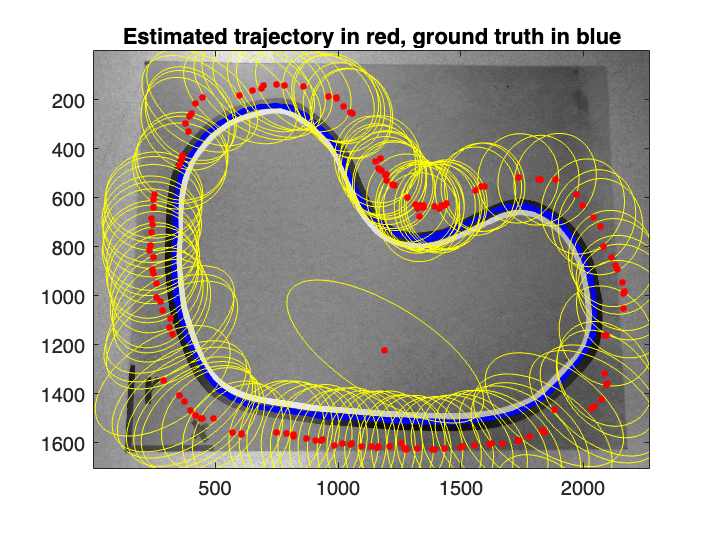

figure(2); clf;
plotresults(th_nls(1:2,:),P_nls(1:2,1:2,:),mic_locations',ground_truth);

## 3. Kalman filtering 

### a) KF algorithm

Implement the Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check if your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_kf,"3a1"))

correct


disp(testmyresult(@timeupdate_kf,"3a2"))

correct


### b) Computation of position estimates with KF

Write your code in the box below, using the given initial position and intial covariance matrix.

Tune $Q$ and $R_k$ as explained in the exercise pdf and comment on your choices.

For $R_k$, we can use the calculated covariance matrices at each timestep in the NLS algorithm. We may just use the top left of these P matrices, as we don't include $\tau$ in the state anymore for the Kalman filter. 

The Q matrix is the covariance of the process noise. In our model, we assume that the robot does not move in between timesteps:


$$p_{k+1} =p_k +w_k$$


Therefore, the noise corresponds to how much we might expect the robot to move in between timesteps. Because the robot moves very slowly relative to our sampling rate, we will want to choose very small values for our covariance matrix. Additionally, we do not expect the x and y movements to be correlated, giving us a diagonal covariance matrix. With these considerations, we tuned the value of Q and found that $Q=\textrm{diag}\left(0\ldotp 5\times {10}^{-6} ,0\ldotp 5\times {10}^{-6} \right)$ gave us the best results. 

R = P_nls(1:2,1:2,:);
Q = eye(2,2)*0.5*1e-6;
P_0 = eye(2,2)*10;
[p_kf,P_kf] = KF(th0(1:2), P_0, R, Q, th_nls((1:2),:));

### c) Visualisation

Plot the mean and covariance of the **filtered** distribution. Uncomment the plot below.

We can see from the plot that the Kalman filter performs much better than the NLS algorithm. The estimate means, shown by the red dots, are much closer to the true values, shown in blue. On top of that, the covariance ovals are much smaller, showing that there is more confidence in the estimate. 

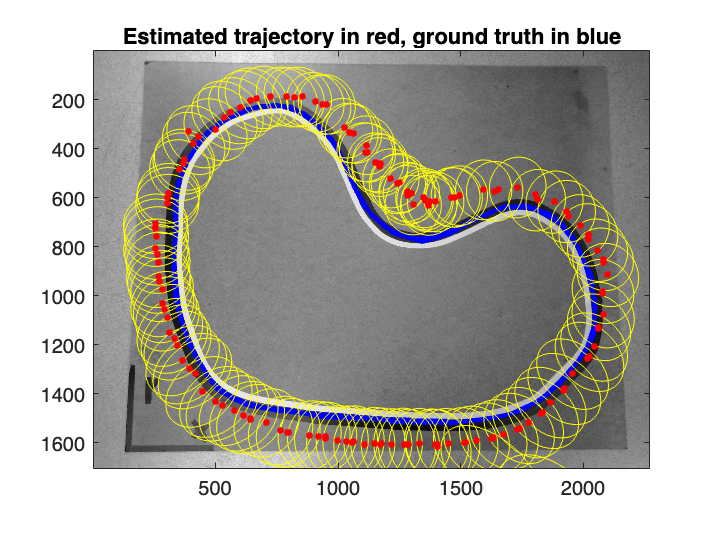

figure(3); clf;
plotresults(p_kf,P_kf,mic_locations',ground_truth);

## 4. Extended Kalman fitering

### a) EKF algorithm

Implement the extended Kalman filter to compute the position estimates in the function templates at the end of this live script. 

Then, uncomment the following two lines to check wheather your implementation is correct. 

**Do not surpress the print, such that it will appear in the exported pdf. **

disp(testmyresult(@measupdate_ekf,"4a1"))

correct


disp(testmyresult(@timeupdate_ekf,"4a2"))

correct


### b) Computation of position estimates with EKF

Tune $Q$ as explained in the exercise pdf and comment on your choices.

Because we are again using a constant value for R, rather than updating it at each time step, we may set $R=\textrm{diag}\left(\sigma_1^2 \ldotp \ldotp \ldotp \sigma_8^2 \right)$based on the noise variances for each microphone that we calculated in the calibration step. 

For the initial covariance matrix $P_0$, we chose $P_0 =10I$. We chose the non-diagonal terms to be zero because we don't expect the uncertainty to have any cross correlation between x, y, and $\tau$ estimates. We chose for the diagonal terms to have a value of 10 because this is quite large  (>10x larger) than the range we expect for our positions and $\tau$. This represents the high uncertainty at the beginning of the simulation before we have received many measurements. 

For the Q matrix, we now have a 3x3 matrix, because $\tau$ is included in our state. We may calculate the variance of $\tau$ using our measurements. We can take the difference between adjacent TOA measurements to get the $\Delta \tau$ values, and then find the variance over all these differences to get the variance of $\tau$. For the rest of the Q matrix, we can use the matrix that we used for the Kalman filter, $Q_k \ldotp$ So, we have:


$$Q=\left\lbrack \begin{array}{cc}
Q_k  & 0\\
0 & \sigma_{\tau }^2 
\end{array}\right\rbrack$$


% Calculation of delta tau for use in timeupdate_ekf 
y_toa_later = y_toa(2:end,:);
y_toa_earlier = y_toa(1:end-1,:);
y_toa_diff = y_toa_later-y_toa_earlier;
delta_tau = mean(y_toa_diff, "all");
var_tau = var(y_toa_diff);

R = diag(vars);
Q = diag([0.5*1e-6, 0.5*1e-6, mean(var_tau)]);
P_0 = eye(3,3)*10;
[th_ekf,P_ekf] = EKF(th0, P_0, y_toa, mic_locations, R, Q);


### c) Visualisation

Plot the mean and covariance of the **filtered** distribution.

The results from the EKF look very similar to the results from the Kalman filter. This tells us that the approximation we made for the Kalman filter ($p_{k+1} =p_k +w_k$) is actually a pretty good approximation of the nonlinear measurement function. As a result, there is little value to be gained from using the EKF over the Kalman filter. Perhaps if the robot was moving faster relative to our sampling rate, the linear approximation for the Kalman filter would no longer hold. In this case, it may be beneficial to use an EKF so as to capture the non-linear behavior. 

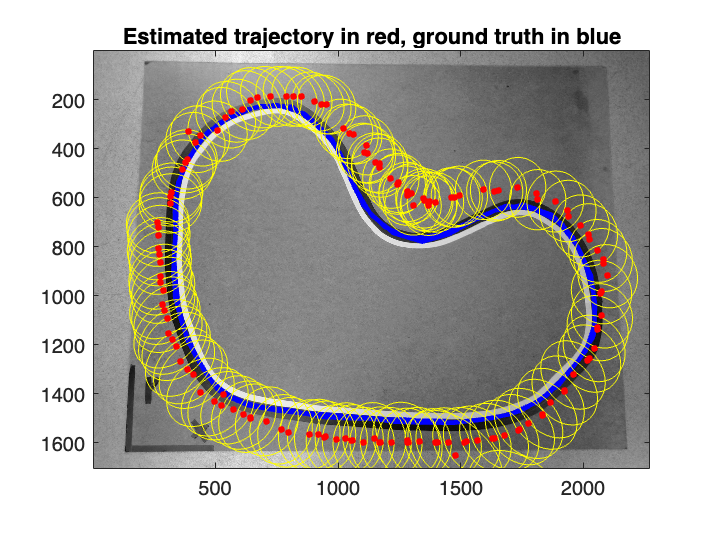

figure(4); clf;
plotresults(th_ekf(1:2,:),P_ekf(1:2,1:2,:),mic_locations',ground_truth);

# Copy all your functions below this text before exporting to PDF!! 

## Functions

NLS

function ftheta = f(theta,mic_locations)
    % INPUT     
    % theta             current state estimate
    % mic_locations     microphonne locations
    % OUTPUT
    % ftheta            evaluation of f at current state estimate
    
    c      = 343; % in [m/s]
    for mic = 1:length(mic_locations)
        ftheta(mic) = theta(3) + (1/c)*norm(theta(1:2) - mic_locations(mic, :)');
    end
    ftheta = ftheta';
end

function dF = Jacobian(theta,mic_locations)
    % INPUT     
    % theta             current state estimate
    % mic_locations     microphonne locations
    % OUTPUT
    % dF                evaluation of Jacobian at current state estimate
    
    c = 343; % in [m/s]

    dF = zeros(8,3);
    for mic = 1:8
        denom = c*norm(theta(1:2)-mic_locations(mic,:)');
        x_diff = theta(1) - mic_locations(mic, 1)';
        y_diff = theta(2) - mic_locations(mic, 2)';
        dF(mic,:) = [x_diff/denom, y_diff/denom, 1];
    end

end

function [th_hat, P_hat] = NLS(yk,th_hat0,R,maxiter,mic_locations)
    % INPUT: 
    % y_k               kth measurement
    % th_hat0           initial estimate
    % R                 covariance matrix of measurement noise
    % maxiter           maximum number of iterations 
    % mic_locations     microphone locations
    
    % OUTPUT    
    % th_hat            mean of kth NLS estimate
    % P_hat             covariance matrix of kth NLS estimate
    
    W = inv(R);
    th_hat(:,1) = th_hat0;
    P_hat(:,:,1) = 10*eye(3,3);

    for iter = 2:maxiter
        F = Jacobian(th_hat(:,iter-1), mic_locations);
        ftheta = f(th_hat(:,iter-1), mic_locations);
        err = yk(iter-1,:)' - ftheta;

        delta_theta = inv(F'*W*F)*F'*W*err;
        th_hat(:,iter) = th_hat(:,iter-1) + delta_theta;
        P_hat(:,:,iter) = inv(F'*W*F);    
    end

end

KF

function [p_kk,P_kk] = timeupdate_kf(p_k,P_k,Q)
    % INPUT
    % p_k   mean of filtering distribution for k|k
    % P_k   covariance matrix of filtering distribution for k|k
    % Q     process noise covariance matrix
    % OUTPUT
    % p_kk  mean of predictive distribution for k+1|k
    % P_kk  covariance of predictive distribution for k+1|k
    
    p_kk = p_k;
    P_kk = P_k + Q;

end

function [p_kf,P_kf] = measupdate_kf(p_k,P_k,R_k,y_k)
    % INPUT
    % p_k   mean of predictive distribution for k|k-1
    % P_k   covariance of predictive distribution for k|k-1
    % R_k   kth measurement noise covariance matrix
    % y_k   kth measurment
    % OUTPUT
    % p_kf  mean of filtering distribution for k|k
    % P_kf  covariance matrix of filtering distribution for k|k

    K_k = P_k*inv(P_k + R_k);
    p_kf = p_k + K_k*(y_k - p_k);
    P_kf = P_k - P_k*inv(P_k + R_k)*P_k;

end

function [p_kf,P_kf] = KF(p_0,P_0,R,Q,y)
    % INPUT: 
    % p_0       prior mean
    % P_0       prior covariance matrix
    % R         Measurement noise covariance matrices for k = 1,...,137
    % Q         Process noise covariance matrix
    % y         Measurements for k = 1,...,137
    % OUTPUT    
    % p_kf      Mean of the filtered distribution for every k
    % P_kf      Covariance matrix of the filtered distribution for every k
    
    p_kf(:,1) = p_0;
    P_kf(:,:,1) = P_0;

    for iter = 2:137
        y_k = y(:,iter);
        R_k = R(:,:,iter);
        [p_kk,P_kk] = timeupdate_kf(p_kf(:, iter-1), P_kf(:,:,iter-1), Q);
        [p_kf(:,iter),P_kf(:,:,iter)] = measupdate_kf(p_kk,P_kk,R_k,y_k);
    end

end

EKF

function [th_kk,P_kk] = timeupdate_ekf(th_k,P_k,Q)
    % INPUT
    % th_k   mean of filtering distribution for k|k
    % P_k    covariance matrix of filtering distribution for k|k
    % Q      process noise covariance matrix
    % OUTPUT
    % th_kk  mean of predictive distribution for k+1|k
    % P_kk   covariance of predicted distribution for k+1|k
    
    th_kk(1:2,1) = th_k(1:2,1);
    th_kk(3,1) = th_k(3,1) + 0.5115;
    P_kk = P_k + Q;

end

function [th_ekf,P_ekf] = measupdate_ekf(th_k,P_k,y_k,mic_locations,R)
    % INPUT
    % th_k              mean of predictive distribution for k|k-1
    % P_k               covariance of predictive distribution for k|k-1
    % y_k               kth measurment
    % mic_locations     microphone locations
    % R                 measurement noise covariance matrix
    % OUTPUT
    % th_ekf            mean of filtering distribution for k|k
    % p_ekf             covariance matrix of filtering distribution for k|k

    H_k = Jacobian(th_k, mic_locations);
    h_k = f(th_k, mic_locations);
    K_k = P_k*H_k'*inv(H_k*P_k*H_k' + R);
    th_ekf1 = th_k;
    th_ekf2 = K_k*(y_k - h_k);
    th_ekf = th_ekf1 + th_ekf2;
    P_ekf = P_k - K_k*H_k*P_k;
end

function [th_ekf,P_ekf] = EKF(th_0,P_0,y,mic_locations,R,Q)
    % INPUT 
    % th_0              prior mean
    % P_0               prior covariance matrix
    % y                 measurements for k = 1,...,137
    % mic_locations     microphone locations
    % R                 measurement noise covariance matrix
    % Q                 process noise covariance matrix
        
    % OUTPUT    
    % th_ekf            mean of the filtering distribution for every k
    % P_ekf             covariance matrix of the filtering distribution for every k    
        
    th_ekf(:,1) = th_0;
    P_ekf(:,:,1) = P_0;

    for iter = 2:137
        y_k = y(iter,:)';
        [th_kk,P_kk] = timeupdate_ekf(th_ekf(:, iter-1), P_ekf(:,:,iter-1), Q);
        [th_ekf(:,iter),P_ekf(:,:,iter)] = measupdate_ekf(th_kk,P_kk,y_k,mic_locations,R);
    end
end